clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;

% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX01312024_gamma2\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

% Loop over each sensor
for sensor_num = 1:num_sensors
    % Get the data for the current sensor (replace with actual data retrieval)
    d_data = eval(['sen', num2str(sensor_num)]);
    
    % Adjust the location for the magnet
    loc = location + [0, 0, 37];
    
    % Data size
    datasize = length(d_data);
    
    % Define the cost function
    dcostfun = @(v) senloc(v, loc, d_data, B_t, datasize);
    
    % Initial guess
    x0 = [0, 0, 0];
    
    % Linear constraints
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    
    % Bounds
    lb = [-100, -100, -100];
    ub = [100, 100, 100];
    
    % Perform optimization and store the result in a cell
    [sensor_results{sensor_num}, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub);
    
    % Display the result
    disp(['Sensor ', num2str(sensor_num), ' Optimization Result:']);
    disp(sensor_results{sensor_num});
    
    % Display the normalized cost
    disp(['Normalized Cost: ', num2str(fval/datasize)]);
    
    % Additional processing or storage of results can be done here
    
    % Add a separator between sensor results
    disp(repmat('-', 1, 40));
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 1 Optimization Result:


       7.9256      -5.1075     -0.72511



Normalized Cost: 4.3625e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 2 Optimization Result:


       2.8881      -4.8727     -0.36673



Normalized Cost: 7.4775e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 3 Optimization Result:


       -1.016      -4.9825     -0.78951



Normalized Cost: 8.796e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 4 Optimization Result:


      -5.5699      -5.0852     -0.70716



Normalized Cost: 6.7549e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 5 Optimization Result:


        8.132      -1.1134     -0.71261



Normalized Cost: 5.3393e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 6 Optimization Result:


       3.2706     -0.50577     -0.42729



Normalized Cost: 5.473e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 7 Optimization Result:


      -1.1217     -0.72895    -0.084845



Normalized Cost: 7.7466e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 8 Optimization Result:


      -5.7648     -0.43735     -0.40927



Normalized Cost: 5.4933e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 9 Optimization Result:


        7.696       4.1493     -0.21602



Normalized Cost: 3.6673e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 10 Optimization Result:


       3.2055       4.0386     -0.20214



Normalized Cost: 4.111e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 11 Optimization Result:


      -1.1662       3.9067     -0.17305



Normalized Cost: 6.9662e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 12 Optimization Result:


      -5.7528       4.0754      -0.5493



Normalized Cost: 6.6735e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 13 Optimization Result:


        7.946       8.3663     -0.49203



Normalized Cost: 6.5301e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 14 Optimization Result:


       3.5354       8.2188      -0.2174



Normalized Cost: 6.6827e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 15 Optimization Result:


      -1.1854       8.2794     -0.25012



Normalized Cost: 5.3778e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 16 Optimization Result:


      -5.4983       8.6206     -0.35892



Normalized Cost: 7.0121e-06


----------------------------------------



% Assign the results to sensor1, sensor2, ...
for sensor_num = 1:num_sensors
    eval(['sensor', num2str(sensor_num), ' = sensor_results{', num2str(sensor_num), '};']);
end

% Initialize arrays to store X and Y coordinates
x_coordinates = zeros(1, num_sensors);
y_coordinates = zeros(1, num_sensors);

% Extract X and Y coordinates from sensor_results
for sensor_num = 1:num_sensors
    eval(['sensor', num2str(sensor_num), ' = sensor_results{', num2str(sensor_num), '};']);
    x_coordinates(sensor_num) = eval(['sensor', num2str(sensor_num), '(1);']);
    y_coordinates(sensor_num) = eval(['sensor', num2str(sensor_num), '(2);']);
end

% Sensor locations in the 4x4 grid
sensor_grid = [
    0, 0;
    -4.5, 0;
    -9.0, 0;
    -13.5, 0;
    0, 4.5;
    -4.5, 4.5;
    -9.0, 4.5;
    -13.5, 4.5;
    0, 9.0;
    -4.5, 9.0;
    -9.0, 9.0;
    -13.5, 9.0;
    0, 13.5;
    -4.5, 13.5;
    -9.0, 13.5;
    -13.5, 13.5
];

sensor_grid = sensor_grid + [13.5/2 -13.5/2]

sensor_grid =          6.75        -6.75
         2.25        -6.75
        -2.25        -6.75
        -6.75        -6.75
         6.75        -2.25
         2.25        -2.25
        -2.25        -2.25
        -6.75        -2.25
         6.75         2.25
         2.25         2.25


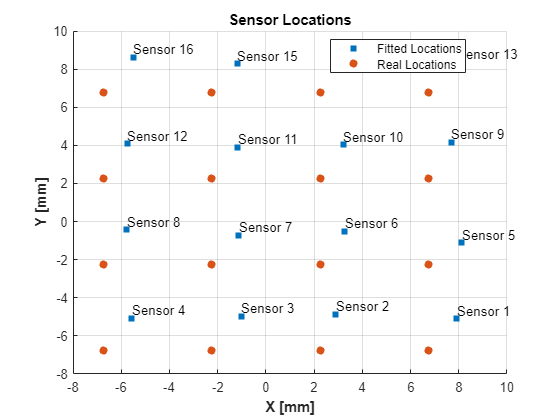


% Plot X and Y coordinates
figure;
scatter(x_coordinates, y_coordinates, 's', 'filled', 'DisplayName', 'Fitted Locations');
hold on;
scatter(sensor_grid(:, 1), sensor_grid(:, 2), 'filled', 'DisplayName', 'Real Locations');
legend('Location', 'Best');
title('Sensor Locations');
xlabel('X [mm]', 'FontWeight','bold');
ylabel('Y [mm]', 'FontWeight','bold');
grid on;
hold off;

% Annotate points with sensor names
for sensor_num = 1:num_sensors
    sensor_name = ['Sensor ', num2str(sensor_num)];
    text(x_coordinates(sensor_num), y_coordinates(sensor_num), sensor_name, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end

corr_x = mean(x_coordinates - sensor_grid(:,1)')

corr_x =        1.0953


corr_y = mean(y_coordinates - sensor_grid(:,2)')

corr_y =        1.6764


sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Loop over each sensor
for sensor_num = 1:num_sensors
    % Get the data for the current sensor (replace with actual data retrieval)
    d_data = eval(['sen', num2str(sensor_num)]);
    sensor = eval(['sensor', num2str(sensor_num)]);
    
    % Data size
    datasize = length(d_data);
    
    % Define the cost function
    dcostfun = @(v) anglecost(v, loc, d_data, B_t, datasize, sensor);
    
    % Nonlinear constraints
    nonlcon = @con;

    % Initial guess
    x0 = [0, 0, 0];

    % Linear constraints
    A = [];
    b = [];
    Aeq = [];
    beq = [];

    % Bounds
    lb = [-1, -1, -1];
    ub = [1, 1, 1];

    % Perform optimization
    [angle_results{sensor_num}, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);

    % Display the result
    disp(['Sensor ', num2str(sensor_num), ' Angle Optimization Result:']);
    disp(angle_results{sensor_num});
    
    % Display the normalized cost
    disp(['Normalized Cost: ', num2str(fval/datasize)]);
    
    % Additional processing or storage of results can be done here
    
    % Add a separator between sensor results
    disp(repmat('-', 1, 40));
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 1 Angle Optimization Result:


  -0.00085436  -0.00077276           -1



Normalized Cost: 4.3689e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 2 Angle Optimization Result:


   0.00022344   -0.0011582           -1



Normalized Cost: 7.4804e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 3 Angle Optimization Result:


  -0.00076998   -0.0011922           -1



Normalized Cost: 8.7936e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 4 Angle Optimization Result:


  -0.00071341   -0.0011006           -1



Normalized Cost: 6.7555e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 5 Angle Optimization Result:


  -0.00045754    0.0011086           -1



Normalized Cost: 5.3435e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 6 Angle Optimization Result:


   -0.0010266     7.77e-05           -1



Normalized Cost: 5.4794e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 7 Angle Optimization Result:


   -0.0005202   -0.0011151           -1



Normalized Cost: 7.7472e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 8 Angle Optimization Result:


  -0.00071414   -0.0010063           -1



Normalized Cost: 5.4955e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 9 Angle Optimization Result:


  -0.00077174   0.00066933           -1



Normalized Cost: 3.6748e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 10 Angle Optimization Result:


   -0.0010785  -0.00022451           -1



Normalized Cost: 4.12e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 11 Angle Optimization Result:


  -0.00072331  -0.00085451           -1



Normalized Cost: 6.9703e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 12 Angle Optimization Result:


  -0.00074587   -0.0010323           -1



Normalized Cost: 6.6759e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 13 Angle Optimization Result:


   -0.0006841    0.0010741           -1



Normalized Cost: 6.5305e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 14 Angle Optimization Result:


   -0.0010432   0.00093619           -1



Normalized Cost: 6.6813e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 15 Angle Optimization Result:


  -0.00086184   0.00083371           -1



Normalized Cost: 5.3805e-06


----------------------------------------



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Sensor 16 Angle Optimization Result:


   -0.0011849  -0.00038983           -1



Normalized Cost: 7.0159e-06


----------------------------------------



% Assign the results to sensor1, sensor2, ...
for sensor_num = 1:num_sensors
    eval(['angle', num2str(sensor_num), ' = angle_results{', num2str(sensor_num), '};']);
end

% Loop to fit locations for the magnet using the angle obtained
for sensor_num = 1:num_sensors
    % Create a variable name for the data
    senave = eval(['sen', num2str(sensor_num)]);
    senlocs = eval(['sensor', num2str(sensor_num)]);
    mangle = eval(['angle', num2str(sensor_num)]);
    loc_corr = eval(['sensor_actual(', num2str(sensor_num),',:)']);

    % Fitting for location using the angle obtained
    sen_preds = [];
    sen_fvals = [];
    locavg = [loc, senave];

    for t = 1:length(d_data)
        B_data = locavg(t, 4:6);
        costfun = @(v)loccost(v, mangle, B_data, B_t, senlocs);
        nonlcon = @con;

        x0 = [0, 0, 35];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-100, -100, 0];
        ub = [100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        sen_preds = [sen_preds; locs];
        sen_fvals = [sen_fvals; fval];
    end
    %sen_preds = sen_preds - loc_corr;
    % Save the results
    variable_name_preds = ['sen', num2str(sensor_num), '_preds'];
    variable_name_fvals = ['sen', num2str(sensor_num), '_fvals'];
    eval([variable_name_preds, ' = sen_preds;']);
    eval([variable_name_fvals, ' = sen_fvals;']);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

sen1_preds

sen1_preds =       -1.8397      -1.5048       36.875
      -2.2534     -0.74495       36.999
       -2.035      0.46078       36.968
      -2.0484       1.2719       36.828
      -1.8081       2.0729       37.031
      -2.0498       3.2226       36.966
     -0.92304      -1.7685       36.964
     -0.84938      -1.0923       36.894
      -1.1943     -0.36671        36.92
      -1.0679       1.0053       36.861


sen1_fvals

sen1_fvals =    2.7657e-09
   1.9355e-09
   1.0108e-09
   6.3846e-09
   9.1247e-10
   7.4522e-10
   2.8998e-10
   2.1514e-09
   2.1367e-09
   5.2528e-09


fixadiff = sen1_preds - loc

fixadiff =       0.16033       0.4952     -0.12502
     -0.25344      0.25505  -0.00062201
    -0.035038      0.46078    -0.032198
    -0.048366      0.27193     -0.17202
      0.19193     0.072937     0.030612
    -0.049823      0.22264    -0.034348
     0.076965       0.2315    -0.036446
      0.15062    -0.092276       -0.106
     -0.19432     -0.36671    -0.079665
    -0.067895    0.0053214     -0.13904


max(fixadiff)

ans =       0.27413       0.4952      0.18171


min(fixadiff)

ans =       -0.2584     -0.36671     -0.17202


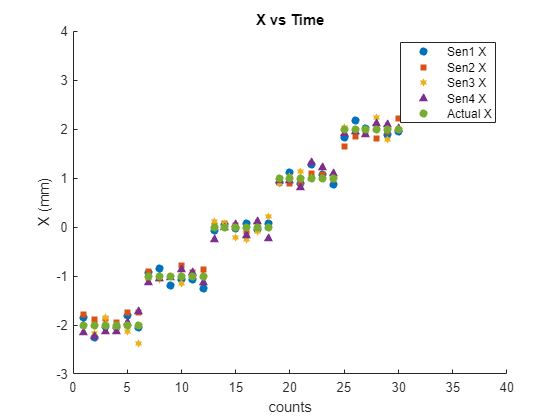

ss1 = sortrows(sen1_preds, 1, 'descend');
ss2 = sortrows(sen2_preds, 1, 'descend');
ss3 = sortrows(sen3_preds, 1, 'descend');
ss4 = sortrows(sen4_preds, 1, 'descend');
ll = sortrows(loc,1, 'descend');
%predicted location using fixed angle
scatter(1:length(sen1_preds),sen1_preds(:,1), 'filled') %x values
hold on;
scatter(1:length(sen2_preds),sen2_preds(:,1), 'filled','square')
scatter(1:length(sen3_preds),sen3_preds(:,1), 'filled','hexagram')
scatter(1:length(sen4_preds),sen4_preds(:,1), 'filled','^')
%title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([0,4])

scatter(1:length(sen1_preds),loc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-2,2])
legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
hold off;


% scatter(1:length(sen1_preds),ss1(:,1), 'filled') %x values
% hold on;
% scatter(1:length(sen2_preds),ss2(:,1), 'filled','square')
% scatter(1:length(sen3_preds),ss3(:,1), 'filled','hexagram')
% scatter(1:length(sen4_preds),ss4(:,1), 'filled','^')
% %title('X vs Time')
% xlabel('counts')
% ylabel('X (mm)')
%ylim([0,4])

% scatter(1:length(sen1_preds),ll(:,1), 'filled')
% title('X Location Comparison')
% xlabel('counts')
% ylabel('X (mm)')
% %ylim([-2,2])
% legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
% hold off;


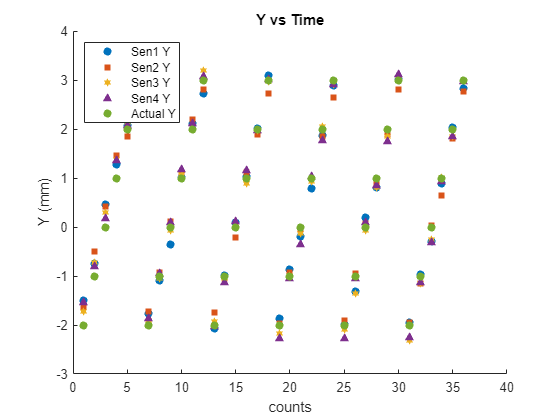

scatter(1:length(sen1_preds),sen1_preds(:,2), 'filled') %y values
hold on;
scatter(1:length(sen1_preds),sen2_preds(:,2), 'filled','square')
scatter(1:length(sen1_preds),sen3_preds(:,2), 'filled','hexagram')
scatter(1:length(sen1_preds),sen4_preds(:,2), 'filled','^')
%title('Fitted Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-1,3])

scatter(1:length(sen1_preds),loc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-2,2])
legend('Sen1 Y','Sen2 Y','Sen3 Y','Sen4 Y', 'Actual Y', Location='northwest')
hold off;

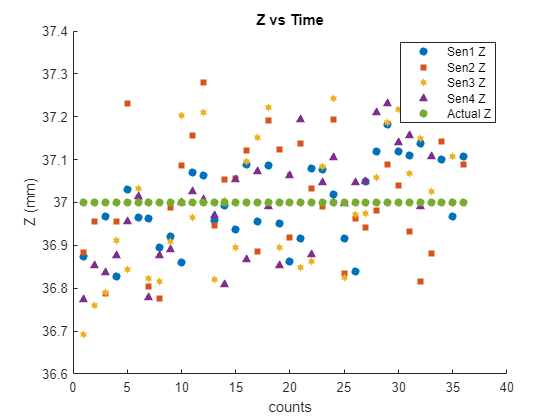

scatter(1:length(sen1_preds),sen1_preds(:,3), 'filled') %z values
hold on;
scatter(1:length(sen1_preds),sen2_preds(:,3), 'filled','square')
scatter(1:length(sen1_preds),sen3_preds(:,3), 'filled','hexagram')
scatter(1:length(sen1_preds),sen4_preds(:,3), 'filled','^')
%title('Fitted Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([39,43])
% scatter(1:length(locavg1),fixadiff(:,1))
% scatter(1:length(locavg1),fixadiff(:,2))
% scatter(1:length(locavg1),fixadiff(:,3))

%actual location of measurement


scatter(1:length(sen1_preds),loc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
legend('Sen1 Z','Sen2 Z','Sen3 Z','Sen4 Z', 'Actual Z')
hold off;

sen1_preds

sen1_preds =       -1.8397      -1.5048       36.875
      -2.2534     -0.74495       36.999
       -2.035      0.46078       36.968
      -2.0484       1.2719       36.828
      -1.8081       2.0729       37.031
      -2.0498       3.2226       36.966
     -0.92304      -1.7685       36.964
     -0.84938      -1.0923       36.894
      -1.1943     -0.36671        36.92
      -1.0679       1.0053       36.861


sen1_fvals

sen1_fvals =    2.7657e-09
   1.9355e-09
   1.0108e-09
   6.3846e-09
   9.1247e-10
   7.4522e-10
   2.8998e-10
   2.1514e-09
   2.1367e-09
   5.2528e-09


fixadiff = sen1_preds - loc

fixadiff =       0.16033       0.4952     -0.12502
     -0.25344      0.25505  -0.00062201
    -0.035038      0.46078    -0.032198
    -0.048366      0.27193     -0.17202
      0.19193     0.072937     0.030612
    -0.049823      0.22264    -0.034348
     0.076965       0.2315    -0.036446
      0.15062    -0.092276       -0.106
     -0.19432     -0.36671    -0.079665
    -0.067895    0.0053214     -0.13904


max(fixadiff)

ans =       0.27413       0.4952      0.18171


min(fixadiff)

ans =       -0.2584     -0.36671     -0.17202


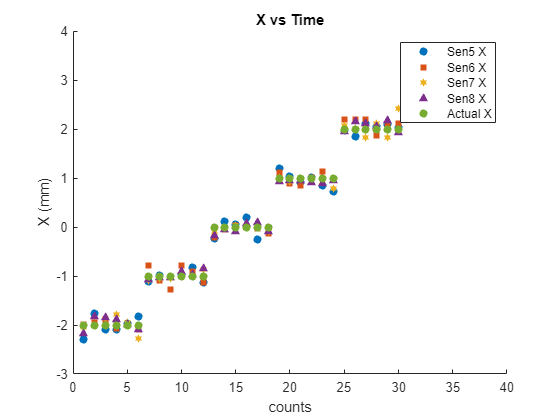

ss1 = sortrows(sen5_preds, 1, 'descend');
ss2 = sortrows(sen6_preds, 1, 'descend');
ss3 = sortrows(sen7_preds, 1, 'descend');
ss4 = sortrows(sen8_preds, 1, 'descend');
ll = sortrows(loc,1, 'descend');
%predicted location using fixed angle
scatter(1:length(sen5_preds),sen5_preds(:,1), 'filled') %x values
hold on;
scatter(1:length(sen6_preds),sen6_preds(:,1), 'filled','square')
scatter(1:length(sen7_preds),sen7_preds(:,1), 'filled','hexagram')
scatter(1:length(sen8_preds),sen8_preds(:,1), 'filled','^')
%title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([0,4])

scatter(1:length(sen1_preds),loc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-2,2])
legend('Sen5 X','Sen6 X','Sen7 X','Sen8 X', 'Actual X')
hold off;


% scatter(1:length(sen1_preds),ss1(:,1), 'filled') %x values
% hold on;
% scatter(1:length(sen2_preds),ss2(:,1), 'filled','square')
% scatter(1:length(sen3_preds),ss3(:,1), 'filled','hexagram')
% scatter(1:length(sen4_preds),ss4(:,1), 'filled','^')
% %title('X vs Time')
% xlabel('counts')
% ylabel('X (mm)')
%ylim([0,4])

% scatter(1:length(sen1_preds),ll(:,1), 'filled')
% title('X Location Comparison')
% xlabel('counts')
% ylabel('X (mm)')
% %ylim([-2,2])
% legend('Sen1 X','Sen2 X','Sen3 X','Sen4 X', 'Actual X')
% hold off;


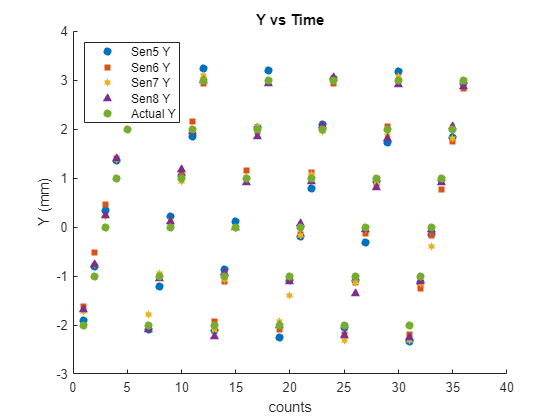

scatter(1:length(sen1_preds),sen5_preds(:,2), 'filled') %y values
hold on;
scatter(1:length(sen1_preds),sen6_preds(:,2), 'filled','square')
scatter(1:length(sen1_preds),sen7_preds(:,2), 'filled','hexagram')
scatter(1:length(sen1_preds),sen8_preds(:,2), 'filled','^')
%title('Fitted Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-1,3])

scatter(1:length(sen1_preds),loc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%ylim([-2,2])
legend('Sen5 Y','Sen6 Y','Sen7 Y','Sen8 Y', 'Actual Y', Location='northwest')
hold off;

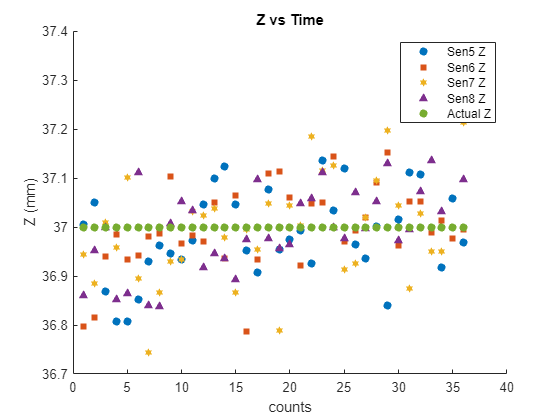

scatter(1:length(sen1_preds),sen5_preds(:,3), 'filled') %z values
hold on;
scatter(1:length(sen1_preds),sen6_preds(:,3), 'filled','square')
scatter(1:length(sen1_preds),sen7_preds(:,3), 'filled','hexagram')
scatter(1:length(sen1_preds),sen8_preds(:,3), 'filled','^')
%title('Fitted Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([39,43])
% scatter(1:length(locavg1),fixadiff(:,1))
% scatter(1:length(locavg1),fixadiff(:,2))
% scatter(1:length(locavg1),fixadiff(:,3))

%actual location of measurement


scatter(1:length(sen1_preds),loc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
legend('Sen5 Z','Sen6 Z','Sen7 Z','Sen8 Z', 'Actual Z')
hold off;

sensor1

sensor1 =        7.9256      -5.1075     -0.72511


sensor2

sensor2 =        2.8881      -4.8727     -0.36673


sensor3

sensor3 =        -1.016      -4.9825     -0.78951


sensor4

sensor4 =       -5.5699      -5.0852     -0.70716



angle1

angle1 =   -0.00085436  -0.00077276           -1


angle2

angle2 =    0.00022344   -0.0011582           -1


angle3

angle3 =   -0.00076998   -0.0011922           -1


angle4

angle4 =   -0.00071341   -0.0011006           -1



sensor_3DA = sensor_actual + sensor11.*[1 1 0] - sensor_actual(11,:)

sensor_3DA =        7.8338      -5.0933            0
       3.3338      -5.0933            0
      -1.1662      -5.0933            0
      -5.6662      -5.0933            0
       7.8338     -0.59331            0
       3.3338     -0.59331            0
      -1.1662     -0.59331            0
      -5.6662     -0.59331            0
       7.8338       3.9067            0
       3.3338       3.9067            0



% Create a cell array to store all rows
all_sen = cell(length(d_data), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(d_data)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[  0.06639 -0.02439 -0.16381]}    {[0.03741 -0.025845 -0.19667]}    {[  0.00813 -0.02637 -0.20183]}    {[  -0.02703 -0.02799 -0.19653]}    {[  0.07005 0.00522 -0.16214]}    {[  0.04254 0.009015 -0.19842]}    {[    0.00807 0.00873 -0.21366]}    {[  -0.029625 0.0105 -0.20393]}    {[ 0.06696 0.040305 -0.15996]}    {[0.039975 0.044655 -0.18578]}    {[ 0.006495 0.047355 -0.19781]}    {[ -0.02913 0.044175 -0.18878]}    {[  0.05946 0.05745 -0.13574]}    {[ 0.03813 0.065415 -0.16105]}    {[   0.00657 0.07212 -0.16947]}    {[ -0.024495 0.07071 -0.16277]}
    {[0.066885 -0.028545 -0.15788]}    {[ 0.03729 -0.03408 -0.19164]}    {[  0.00936 -0.033795 -0.1974]}    {[-0.025845 -0.033285 -0.19329]}    {[ 0.06744 -0.00225 -0.16533]}    {[    0.042255 6e-05 -0.19888]}    {[  0.007875 0.000405 -0.21519]}    {[  -0.03201 0.00282 -0.20205]}    {[   0.067605 0.03315 -0.165]}    {[ 0.04278 0.036165 -0.19089]}    {[ 0.006585 0.036075 -0.20367]}    {[ -0.028485 0.03702 -0.19091

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =      0.038439    -0.016726     -0.96802
     0.018255    -0.080828     -0.99398
    0.0082373    -0.097572     -0.97924
    -0.015035    -0.089994     -0.96505
     0.024593     -0.15605     -0.99229
    -0.020831      -0.1481     -0.95598
     0.026634    -0.016873     -0.95831
     0.015216    -0.051126     -0.99097
    -0.019821    -0.091266     -0.98816
    -0.011754     -0.18339     -0.99679


multiloc = multipreds(:,4:6) + [corr_x corr_y 0]

multiloc =       -2.5218      -1.4543        36.91
      -2.2271      0.39825       37.294
      -2.0338       1.5769       37.078
      -1.7654       2.4858       36.926
      -2.2779        4.206        37.28
      -1.7456       5.1611       36.825
      -1.3528       -1.703       36.806
      -1.2386     -0.31026       37.243
     -0.76716       1.2094       37.295
     -0.80649       3.4515       37.435


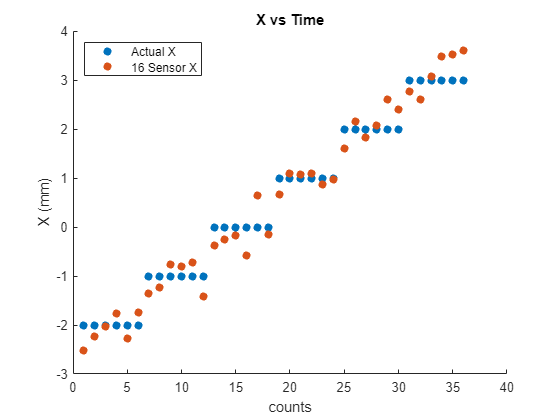

scatter(1:length(sen1_preds),loc(:,1), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,1), 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

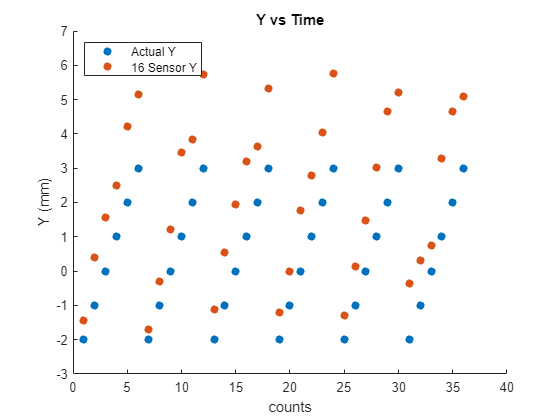

scatter(1:length(sen1_preds),loc(:,2), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,2), 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
ylim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

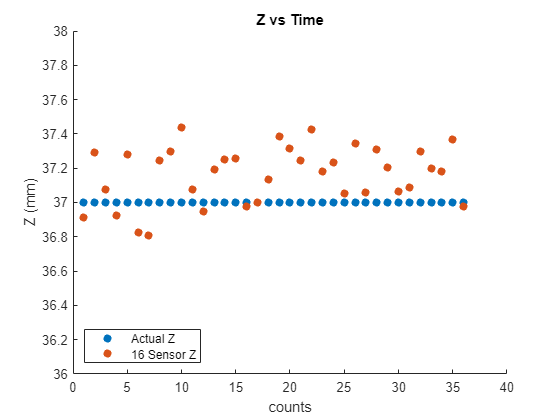

scatter(1:length(sen1_preds),loc(:,3), 'filled')
hold on;
scatter(1:length(sen1_preds), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
ylim([36,38])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

test = diff(multiloc(:,1))

test =       0.29471
      0.19326
      0.26843
      -0.5125
      0.53225
       0.3928
      0.11424
      0.47143
    -0.039336
     0.073818


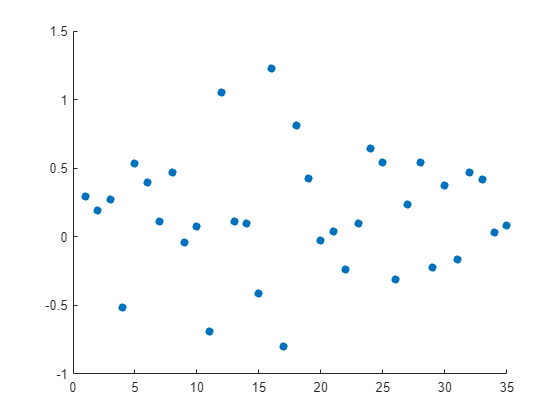

scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -37]

multidisp =      -0.52179      0.54568    -0.089652
     -0.22707       2.3983      0.29406
    -0.033811       3.5769     0.078256
      0.23462       4.4858    -0.073831
     -0.27788        6.206      0.27975
      0.25437       7.1611     -0.17534
      0.64717      0.29697     -0.19423
      0.76141       1.6897      0.24295
       1.2328       3.2094      0.29472
       1.1935       5.4515      0.43517


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =       0.76031
       2.4269
       3.5779
       4.4925
       6.2185
       7.1677
      0.73807
       1.8692
       3.4506
       5.5976



disp = [0.04 1 2.04 3.06 4.09 5.08 1.01 1.49 2.29 3.16 4.12 5.09 2.01 2.25 2.86 3.66 4.57 5.44 3.01 3.19 3.61 4.25 5.04 5.9 4.01 4.13 4.50 5.02 5.69 6.45 5.01 5.10 5.42 5.86 6.46 7.15]'

disp =          0.04
            1
         2.04
         3.06
         4.09
         5.08
         1.01
         1.49
         2.29
         3.16


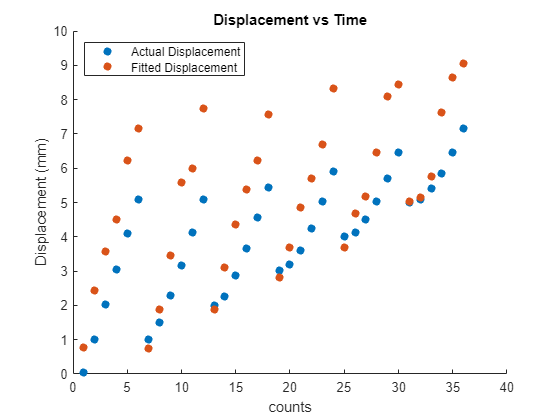


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end